## NUMERICAL METHODS - Lab 3

## Task 1

for i = 1:3:3*5
    i
end

i = 1

i = 4

i = 7

i = 10

i = 13

## Task 2

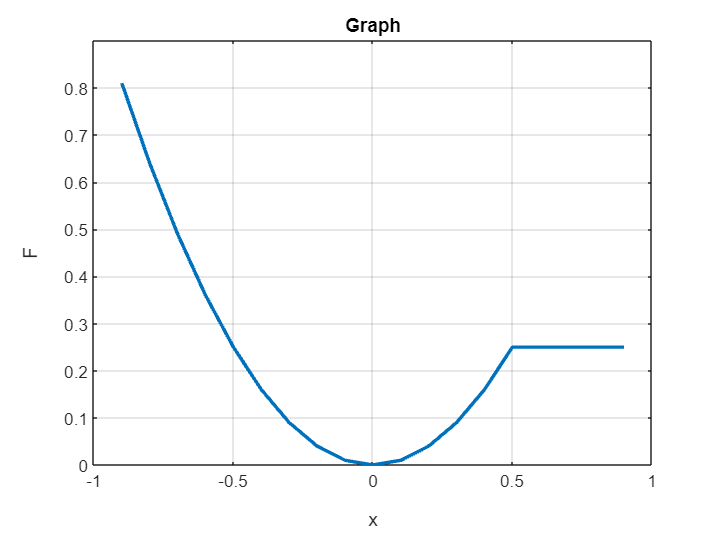

% Define the range of x values
x_values = -1:0.1:1;

% Initialize an array for values of F
F_values = zeros(size(x_values));

% Iterate through each value of x
for i = 1:length(x_values)
    x = x_values(i);
    
    if -1 < x && x < 0.5
        F_values(i) = x^2;
    elseif 0.5 <= x && x < 1
        F_values(i) = 0.25;
    else
        F_values(i) = NaN; 
    end
end

% Plot the graph
plot(x_values, F_values, 'LineWidth', 2);
title('Graph');
xlabel('x');
ylabel('F');
grid on;

## Task 3

Find the Taylor polynomial near x= 1 for f(x) = lnx.

syms x;
f = log(x);
taylor_poly = taylor(f, x, 'ExpansionPoint', 1, 'Order', 3);
disp(taylor_poly);

$$x-\frac{{\left(x-1\right)}^{2}}{2}-1$$

For the Taylor polynomials of orders 1, 3, and 5 near *x*=0 for *f*(*x*)=sin(*x*):

syms x;
f = sin(x);
taylor_poly_1 = taylor(f, x, 'ExpansionPoint', 0, 'Order', 1);
taylor_poly_3 = taylor(f, x, 'ExpansionPoint', 0, 'Order', 3);
taylor_poly_5 = taylor(f, x, 'ExpansionPoint', 0, 'Order', 5);

disp(taylor_poly_1);

$$0$$

disp(taylor_poly_3);

$$x$$

disp(taylor_poly_5);

$$x-\frac{x^{3}}{6}$$